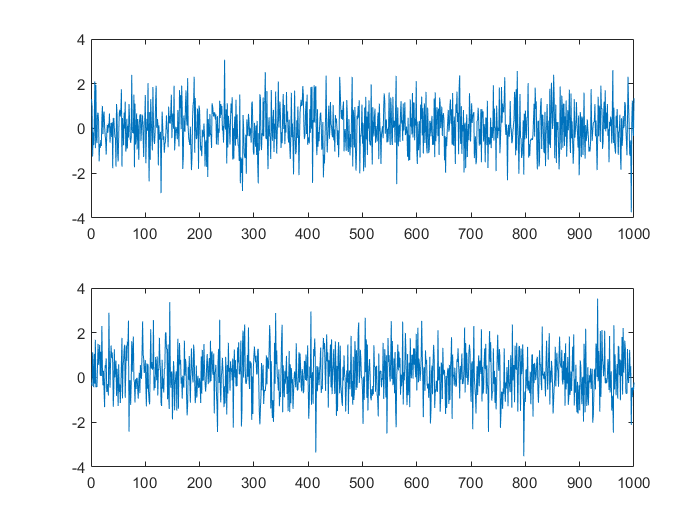

miu1=0;
miu2=0.2;
fangcha=1;
sig1=miu1+fangcha.*randn(1000,1);
sig2=miu2+fangcha.*randn(1000,1);

figure(1)
subplot(2,1,1)
plot(sig1)

subplot(2,1,2)
plot(sig2)

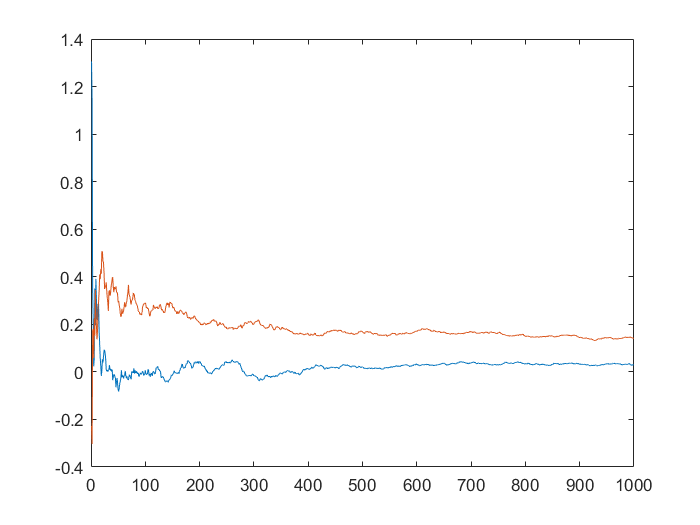

figure(2)
ave1=zeros(1,1000);
ave2=zeros(1,1000);

for i=1:1:1000
    for j=1:1:i
        ave1(i)=(ave1(i)+sig1(j));
        ave2(i)=(ave2(i)+sig2(j));
    end
    ave1(i)=ave1(i)/i;
    ave2(i)=ave2(i)/i;
end
plot(ave1);
hold on;
plot(ave2);

the average value of ave1 is around 0 while the value of ave2 is getting bigger

we can separate sig by using average. because the average of random noise is close to 0 while the average of sig is close to its means. 